The purpose of this document to investigate the obtained linear crane model from current into the motor to horizontal position of the container and design a controller for the system.

Definiation of variabels

g=9.82;         %gravity
B=11;           %dynamic friction [N]               %!!!Esimated by LL
mC=2.942;       %mass of container
mH=0.951;       %mass of head
m1=0.792;       %mass of trolley
ke=0.0296;      %motor constant (electric) from datasheet
r1=0.16;        %radius of outer trolley gear       
I1=1.2e-3;      %moment of inertia of trolley gear  
l=1;            %length of wire                     %!!!Variable
tg=48/12*72/14  %Torque gearing relationship

tg = 20.5714

Derived variabels used in model

M=mC+mH;            %Mass of head and container
M1=M+m1+I1/r1^2;
b1=M/M1;

Crane model

s=tf('s');
Crane = (-ke*tg*g/(r1*M1))/(s^4*(l-b1*l)+s^3*B/M1+s^2*g+s*B*g/M1)

Crane =
 
                    -176.8
  -------------------------------------------
  3.969 s^4 + 52.05 s^3 + 219.9 s^2 + 511.1 s
 
Continuous-time transfer function.



pole(Crane)

ans =    0.0000 + 0.0000i
  -8.3127 + 0.0000i
  -2.4000 + 3.1193i
  -2.4000 - 3.1193i


# Controller design

Det vælges i første omgang at designe kontroller med udgangspunkt i B=3.5. Dette er to oktaver under estimatet fra Peter

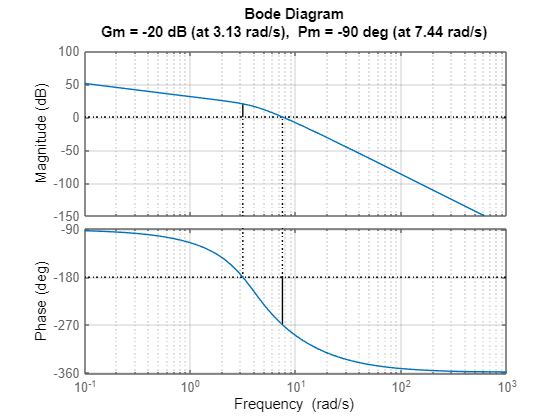

margin(-Crane*100)
grid on

Det vuderes nødvendigt at hæve båndbredde. Dette gøres ved brug af en lead kompensering. Det vælges at hæve fasen 55 grader i 2 rad.


$$\sin(\phi))\frac{1-\alpha}{1+\alpha} =>\alpha=0.099406$$


Det vælges at lægge cross over i 1 rad/s


$$\omega_{max}=\frac{1}{T_d\cdot\sqrt{\alpha}} =>T_d=3.17$$


Td=1.5;
alpha=0.099;
lead=(Td*s+1)/(alpha*Td*s+1)

lead =
 
   1.5 s + 1
  ------------
  0.1485 s + 1
 
Continuous-time transfer function.



Plot of lead controller

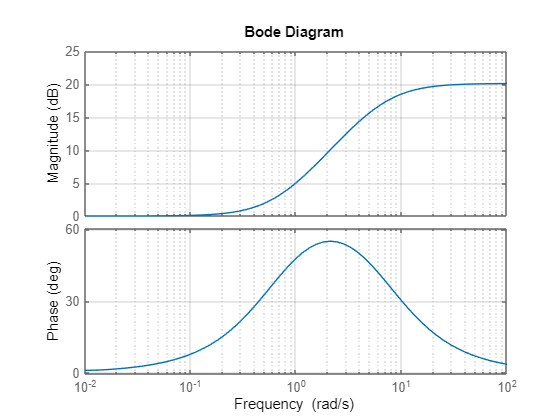

bode(lead)
grid on

Controlleren har de ønskede spesifikationer. Plotter sammen med plantet.

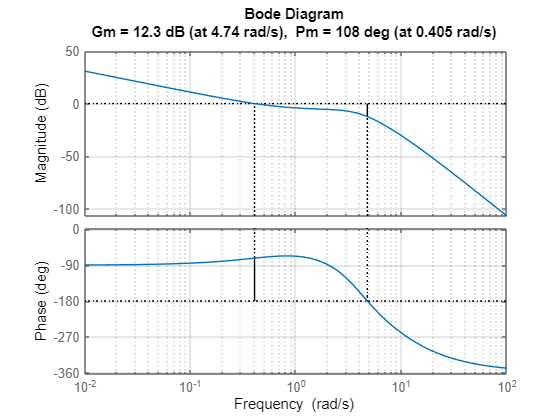

margin(-Crane*lead)
grid on

Gainet hæves så cross over findes ved 2 rad.

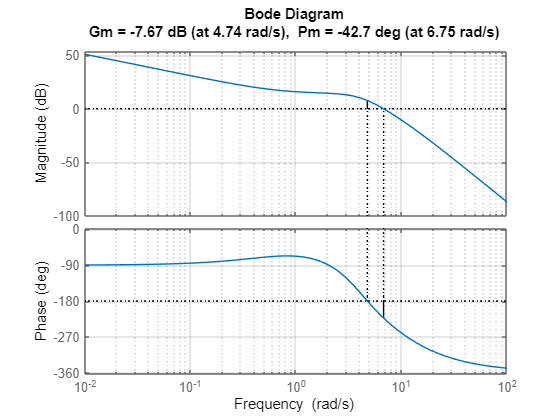

margin(-Crane*lead*10)
grid on

Der er en fin fasemargen men en lidt lille gain margin.

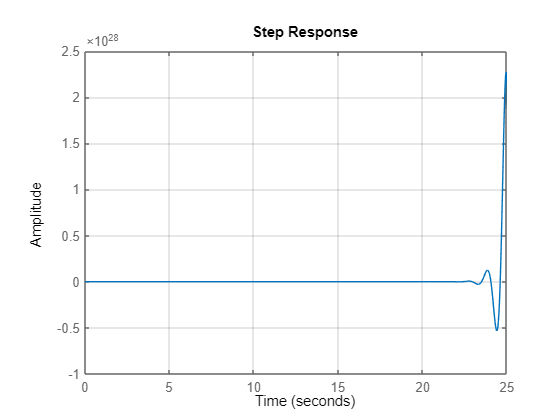

step(feedback(-Crane*100,1))
grid on